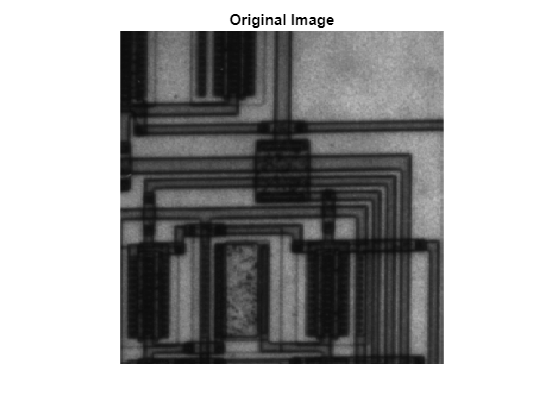

%  Read Image
img = imread('pic2.png');
figure;
imshow(img);
title('Original Image');

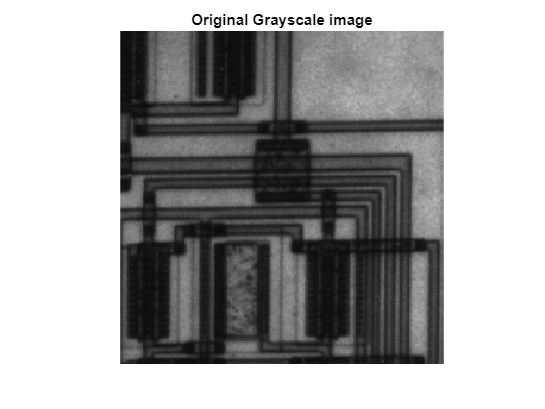

% Converting the image to grayscale if its not in grayscale
imgGray = im2gray(img); 
m='mat';
figure;
imshow(imgGray);
title('Original Grayscale image');

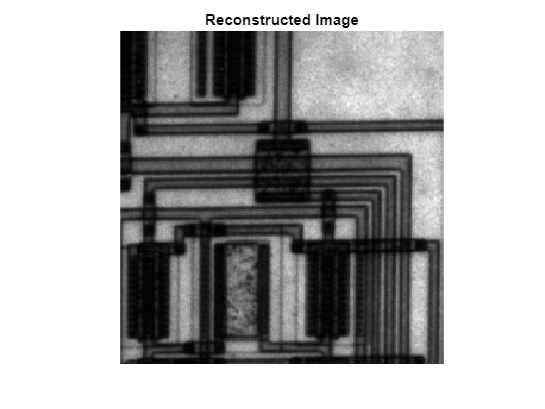

reconstructedImg =     0.0588    0.0588    0.0588    0.0549    0.0588    0.0588    0.0627    0.0627    0.0706    0.0784    0.0980    0.1098    0.0980    0.0824    0.0745    0.0706    0.0745    0.0745    0.0784    0.0824    0.1020    0.1216    0.1529    0.2549    0.2980    0.3490    0.3686    0.4000    0.3451    0.3059    0.3098    0.3412    0.3686    0.3608    0.3608    0.3765    0.4431    0.4431    0.4118    0.4235    0.4471    0.4784    0.4941    0.4706    0.4745    0.4941    0.5020    0.4784    0.4706    0.4902
    0.0627    0.0549    0.0549    0.0549    0.0588    0.0588    0.0588    0.0588    0.0627    0.0784    0.0941    0.1059    0.0941    0.0824    0.0784    0.0627    0.0627    0.0745    0.0745    0.0784    0.0980    0.1137    0.1569    0.2706    0.3137    0.3608    0.3725    0.4039    0.3608    0.3059    0.3216    0.3608    0.4000    0.4000    0.4157    0.3922    0.4196    0.4157    0.4275    0.4431    0.4627    0.4706    0.4706    0.4627    0.4667    0.4941    0.4941    0.4824

% function call to perform the wavelet transform and save the coefficients
[LL, HL, LH, HH] = performWaveletTransform(imgGray); 
% performing inverse wavelet transform to reconsturct the image
reconstructedImg = performInverseWaveletTransform(LL, HL, LH, HH)

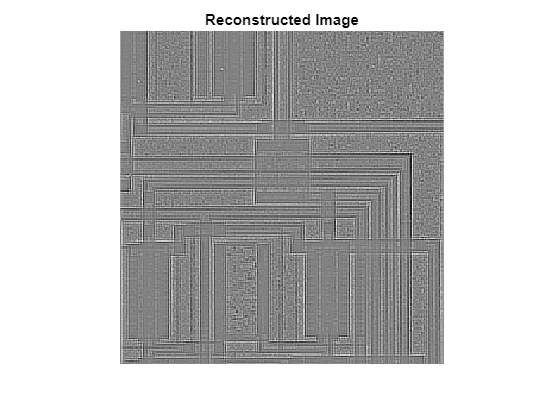

reconstructedImg =     0.0000    0.0000    0.0029   -0.0010    0.0000    0.0000    0.0020    0.0020   -0.0020    0.0059   -0.0039    0.0078    0.0088   -0.0069    0.0029   -0.0010    0.0029    0.0029    0.0000    0.0039   -0.0069    0.0127   -0.0559    0.0461   -0.0324    0.0186   -0.0176    0.0137    0.0157   -0.0235   -0.0235    0.0078   -0.0137   -0.0216   -0.0255   -0.0098    0.0127    0.0127   -0.0147   -0.0029   -0.0176    0.0137    0.0196   -0.0039   -0.0078    0.0118    0.0127   -0.0108   -0.0029    0.0167
    0.0039   -0.0039   -0.0010   -0.0010   -0.0000   -0.0000   -0.0020   -0.0020   -0.0098    0.0059   -0.0078    0.0039    0.0049   -0.0069    0.0069   -0.0088   -0.0088    0.0029   -0.0039   -0.0000   -0.0108    0.0049   -0.0520    0.0618   -0.0167    0.0304   -0.0137    0.0176    0.0314   -0.0235   -0.0118    0.0275    0.0176    0.0176    0.0294    0.0059   -0.0108   -0.0147    0.0010    0.0167   -0.0020    0.0059   -0.0039   -0.0118   -0.0157    0.0118    0.0049   -0.0069

% Reconstruct image without LL subband
reconstructedImg = performInverseWaveletTransform([], HL, LH, HH)

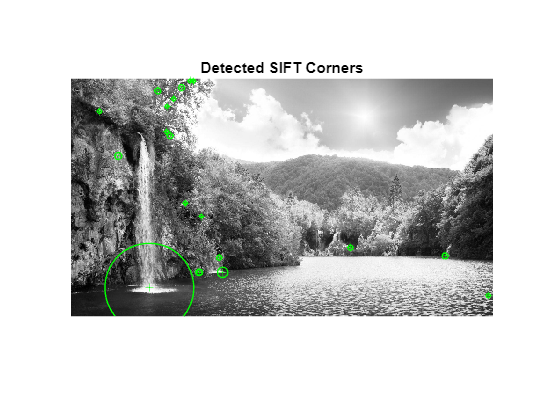

% Detect corners in the imput image
img2 = imread("pic1.png");
img2 = im2gray(img2);
% detect corners in the input image
detectSIFT(img2);

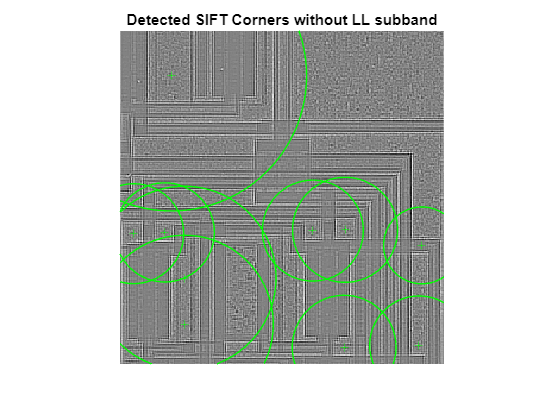

detectSIFT1([], HL, LH, HH, imgGray);

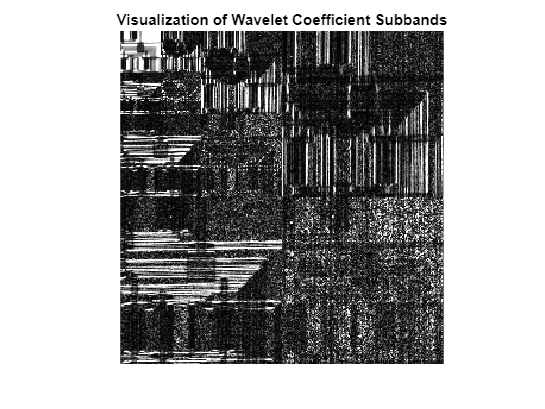

% function call for wavelet reconstruction without the LL Subband
% Performing wavelet transform for multiple levels

[coeff, s] = wavedec2(imgGray, 3, 'db1');
% Level 1 approximation
LL1 = appcoef2(coeff, s, 'db1', 1); 
[HL1, LH1, HH1] = detcoef2('all', coeff, s, 1);
% Level 2 approximation
LL2 = appcoef2(coeff, s, 'db1', 2);
[HL2, LH2, HH2] = detcoef2('all', coeff, s, 2);
% Level 3 approximation
LL3 = appcoef2(coeff, s, 'db1', 3); 
[HL3, LH3, HH3] = detcoef2('all', coeff, s, 3);

% Performing and scaling the matrices to required size for level 1
% scaling the LH subband of level 1 
LH1Scale = wcodemat(LH1, 512, m, 1);
% scaling the HL subband of level 1 
HL1Scale = wcodemat(HL1, 512, m, 1);
% scaling the HH subband of level 1 
HH1Scale = wcodemat(HH1, 512, m, 1);
% scaling the LL subband of level 1 
LL1Scale = wcodemat(LL1, 512, m, 1);

% Performing and scaling the matrices to required size for level 2
% scaling the LH subband of level 2
LH2Scale = wcodemat(LH2, 512, m, 1);
% scaling the HL subband of level 2 
HL2Scale = wcodemat(HL2, 512, m, 1);
% scaling the HH subband of level 2
HH2Scale = wcodemat(HH2, 512, m, 1);
% scaling the LL subband of level 2
LL2Scale = wcodemat(LL2, 512, m, 1);

% Performing and scaling the matrices to required size for level 3
% scaling the LH subband of level 3
LH3Scale = wcodemat(LH3, 512, m, 1);
% scaling the HL subband of level 3
HL3Scale = wcodemat(HL3, 512, m, 1);
% scaling the HH subband of level 3
HH3Scale = wcodemat(HH3, 512, m, 1);
% scaling the LL subband of level 3
LL3Scale = wcodemat(LL3, 512, m, 1);

% to construct the subband matrices for level 3
Sub3 = [LL3Scale, LH3Scale; HL3Scale, HH3Scale]; % 
% to construct the subband matrices for level 2
Sub2 = [Sub3, LH2Scale; HL2Scale, HH2Scale]; 
% to construct the subband matrices for overall
Sub1 = [Sub2, LH1Scale; HL1Scale, HH1Scale];


imshow(uint8(Sub1))
title('Visualization of Wavelet Coefficient Subbands');

% function to perform wavelet transform

function  [LL, HL, LH, HH] = performWaveletTransform(grayImage) 
    % Performing wavelet decomposition using haar
    [LL, HL, LH, HH] = dwt2(im2double(grayImage), 'haar');
    imwrite([LL,HL,LH,HH],"waveCoef.png");
    save('waveCoef.mat', 'LL', 'HL', 'LH', 'HH');    
end

function reconstructedImage = performInverseWaveletTransform(LL, HL, LH, HH)
% Perform inverse wavelet transform
    reconstructedImage = idwt2(LL, HL, LH, HH, 'haar'); 
    imwrite(reconstructedImage,"inverseWaveCoef.png");
    figure; 
    imshow(reconstructedImage, []);
    title('Reconstructed Image');
end

% Plotting the detected corners to the wavelet reconstruction (without LL subband)
function detectSIFT1(LL, HL, LH, HH, imgGray)
% Perform inverse wavelet transform
    reconstructedImage = idwt2(LL, HL, LH, HH, 'haar'); 
    features = detectSIFTFeatures(imgGray);
    imwrite(reconstructedImage,"inverseWaveCoef.png");
    figure;imshow(reconstructedImage, []);
    hold on;
    plot(features.selectStrongest(10)); 
    title('Detected SIFT Corners without LL subband'); 
    hold off;
end
% Plotting the detected corners to the wavelet reconstruction (without LL subband)
function detectSIFT(grayImage) 
    % Find corners with SIFT 
    features = detectSIFTFeatures(grayImage); 
    figure; imshow(grayImage);
    hold on;
    plot(features.selectStrongest(20)); 
    title('Detected SIFT Corners'); 
    hold off;
end










